# MECH 6323 - Homework 6

Author: Jonas Wagner

Date: 2022-04-10

clear
close all

## Problem 1

#### Part a

#### 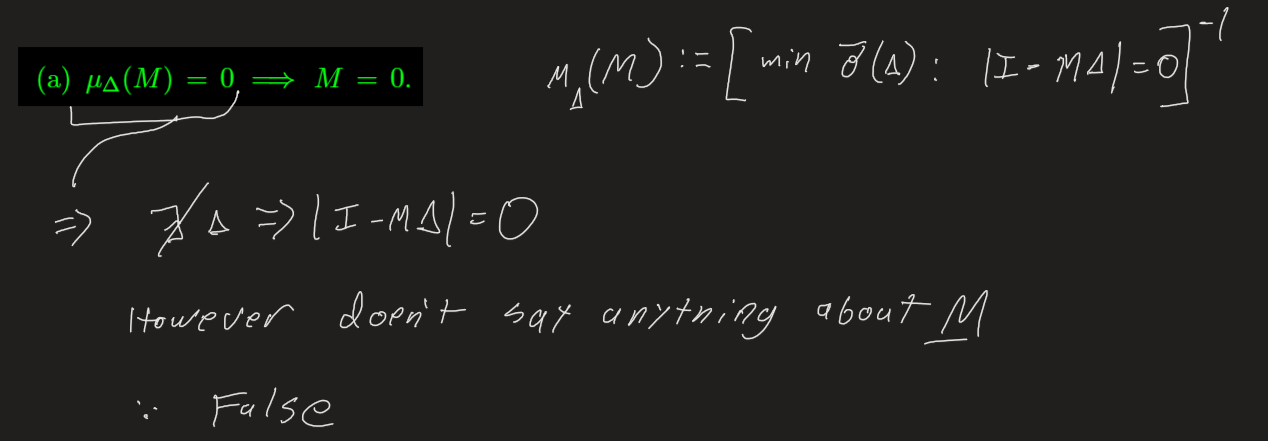

#### Part b

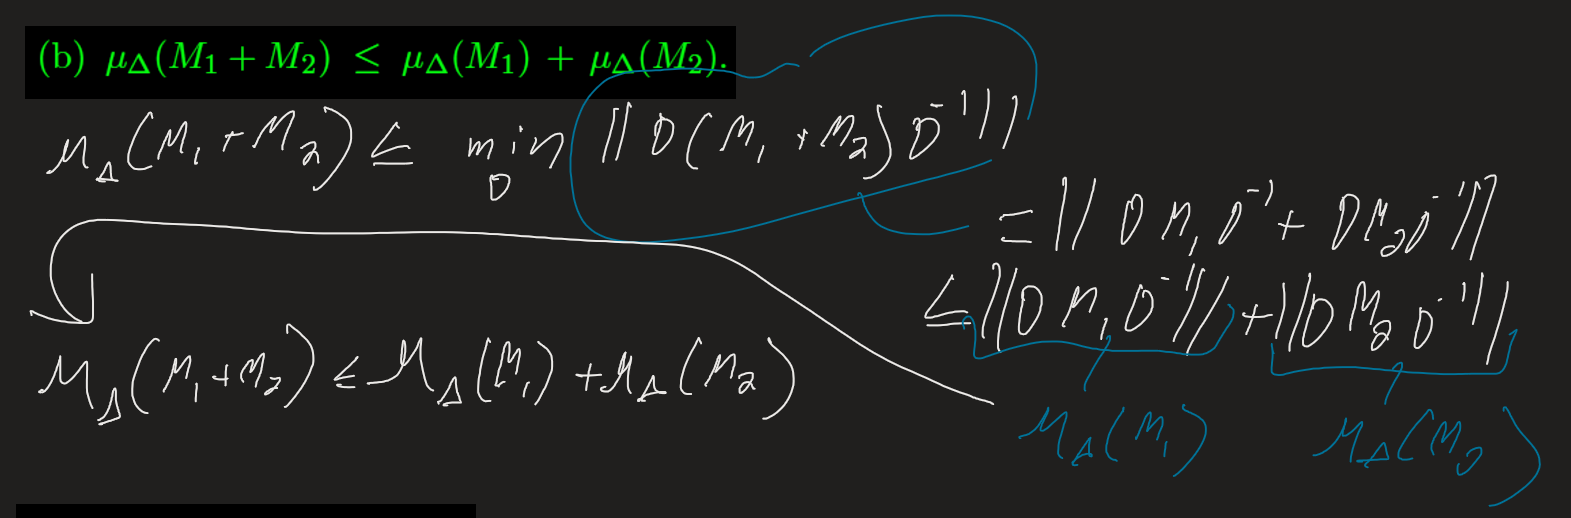

#### Part c

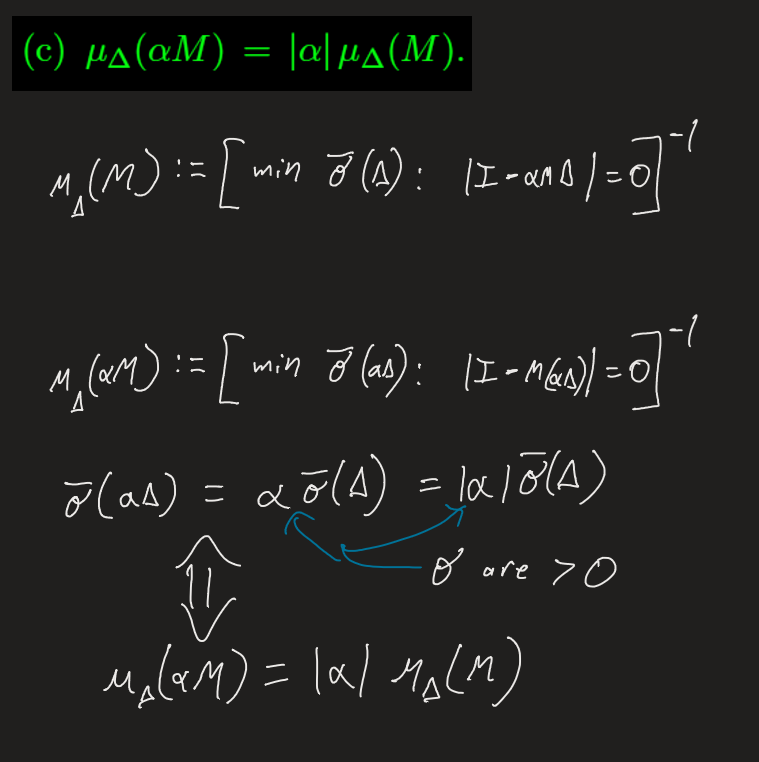

#### Part d

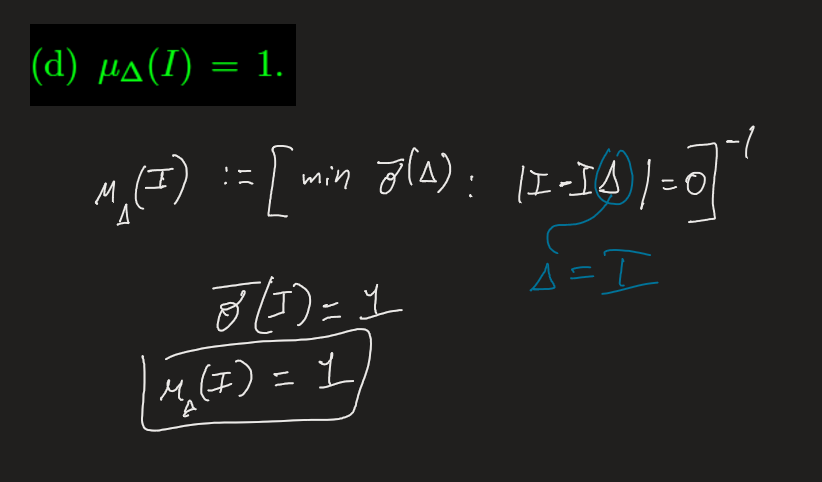

#### Part e

N = sym('n',2,'real');
M = sym('m',2,'real');
MN = M*N;
sigma_delta_1 = max(svd(M));
mu_delta_2 = 1/max(svd(N\eye(2)));
mu_delta = 1/max(svd(MN\eye(2)));
solve(mu_delta > sigma_delta_1 + mu_delta_2, {M,N})

#### Part f

N = sym('n',2,'real');
M = sym('m',2,'real');
MN = M*N;
sigma_delta_1 = max(svd(N));
mu_delta_2 = 1/max(svd(M\eye(2)));
mu_delta = 1/max(svd(MN\eye(2)));
solve(mu_delta <= sigma_delta_1 + mu_delta_2,{M,N})

## Problem 2

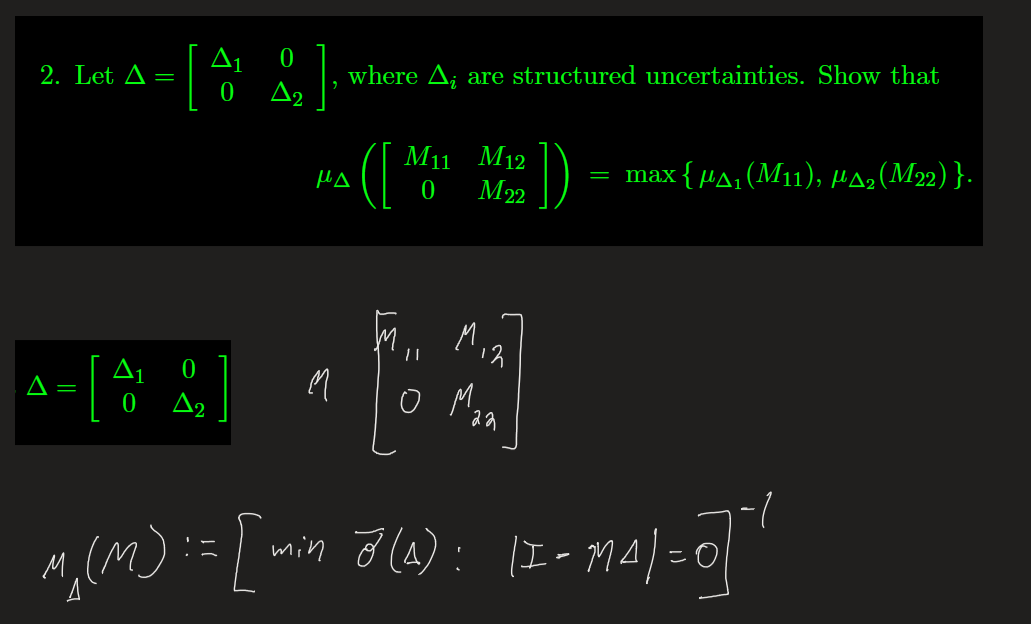

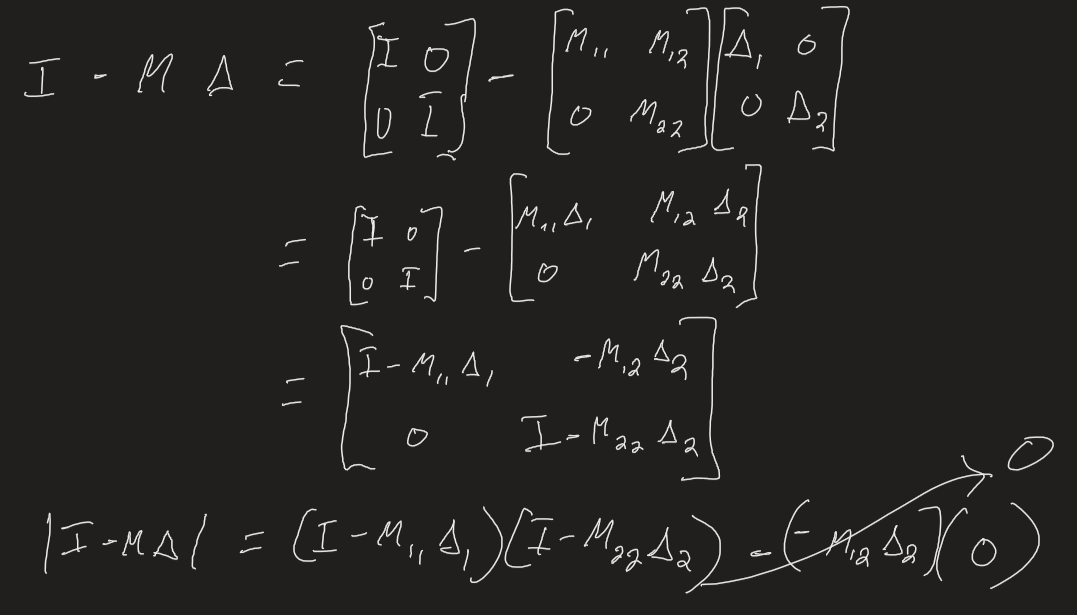

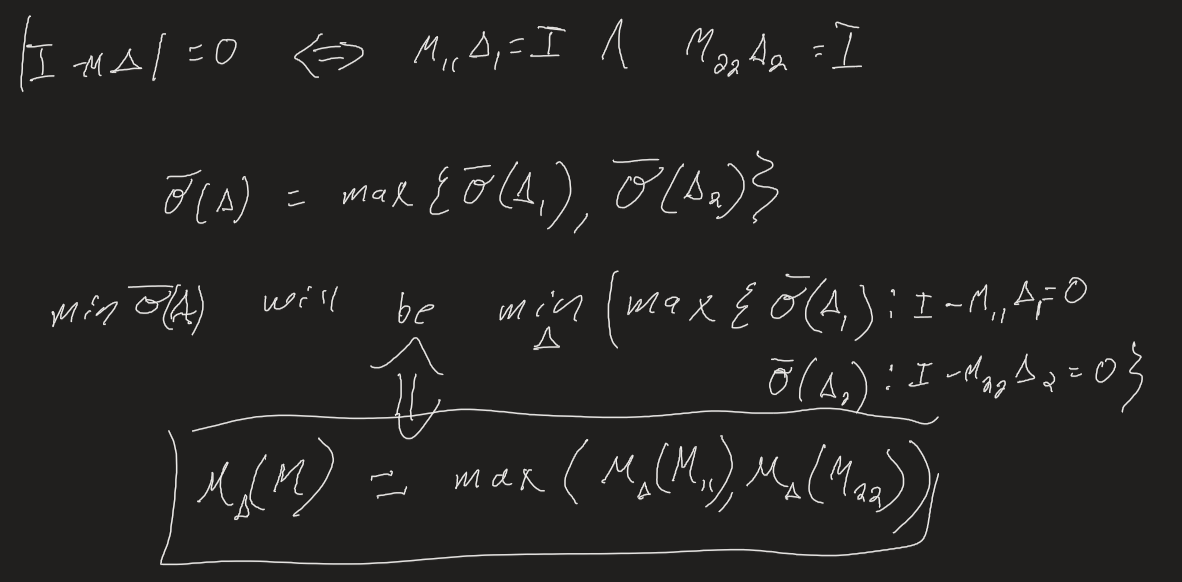

## Problem 3

tol_0 = 0.001;
%from simplemu.m
% Example data
i=sqrt(-1);
mat=[0.10+0.07*i -0.1538+0.1615*i 0-0.56*i  0+42.0*i  4.-1.4*i 
 0-0.2730*i -0.30-0.28*i 2.86+0.546*i -26.0+72.8*i 13.+5.4600*i
 0.10+0.1750*i 0.0769-0.1077*i -0.40+0.2100*i 5.0+3.5000*i 4.5-0.70*i
  0+0.0021*i -0.0038-0.0021*i 0.0060+0.0112*i 0.2000+0.4200*i  0.0600+0.0140*i
 0.0240+0.0280*i 0+0.0269*i -0.0660+0.0420*i 0+0.70*i -0.4210+0.49*i
];

% Sample uncertainty structures
blka = [5 0];
blkb = [3 0;2 0];
blkc = [1 1;1 1;1 1;2 0];
blkd = [1 1;1 1;1 1;1 1;1 1];
blke = [2 2;2 2;1 1];
blkf = [2 2;3 3];
blkg = [5 5];
blkh = [2 3;3 2];
blki = [1 4;4 1];

% Run easymu
[upp,low,pert,dleft,dright] = easymu(mat,blka);
[low,upp];

#### blke

[upp,low,pert,dleft,dright] = easymu(mat,blke);
pert

pert =   -0.0164 - 0.0447i  -0.0552 - 0.0645i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0275 - 0.0026i   0.0444 - 0.0215i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0048 - 0.0024i  -0.0003 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0915 - 0.0650i   0.0028 - 0.0053i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0845 - 0.0744i


low

low = 8.8836

norm(pert)

ans = 0.1126

1/norm(pert)

ans = 8.8836

low - 1/norm(pert) < tol_0

ans = logical
   1


they be inversly related

det(eye(size(mat)) - mat*pert)

ans = 3.7583e-16 - 6.3936e-18i

det(eye(size(mat)) - mat*pert) < tol_0

ans = logical
   1


Which is essentially 0

upp

upp = 8.9017

norm(dleft*mat/dright)

ans = 8.9016

upp - norm(dleft*mat/dright) < tol_0

ans = logical
   1


#### blkf

[upp,low,pert,dleft,dright] = easymu(mat,blkg);
pert

pert =   -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 + 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i
   0.0001 + 0.0000i   0.0003 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 - 0.0052i  -0.0033 - 0.0091i   0.0006 - 0.0005i   0.0000 - 0.0001i  -0.0000 - 0.0001i
   0.0009 - 0.0000i   0.0015 - 0.0006i   0.0001 + 0.0001i   0.0000 + 0.0000i   0.0000 - 0.0000i


low

low = 89.4127

norm(pert)

ans = 0.0112

1/norm(pert)

ans = 89.4127

low - 1/norm(pert) < tol_0

ans = logical
   1


they be inversly related

det(eye(size(mat)) - mat*pert)

ans = -4.0660e-16 - 7.9568e-18i

det(eye(size(mat)) - mat*pert) < tol_0

ans = logical
   1


Which is essentially 0

upp

upp = 89.4127

norm(dleft*mat/dright)

ans = 89.4127

upp - norm(dleft*mat/dright) < tol_0

ans = logical
   1


## Problem 4

#### Naive methods (for speed of writing)

% Parameters
m = 2150; %kg
b = 20; %N s/m
c = 150; %N/deg
tau = 0.1; %s
% System Definition
U_cmd = tf([1],[tau 1])

U_cmd =
 
      1
  ---------
  0.1 s + 1
 
Continuous-time transfer function.



P = U_cmd * tf([c], [m b])

P =
 
           150
  ---------------------
  215 s^2 + 2152 s + 20
 
Continuous-time transfer function.



#### Part a

B = zpk(tf([1 0.02], [0.5 1]))

B =
 
  2 (s+0.02)
  ----------
    (s+2)
 
Continuous-time zero/pole/gain model.



The magnitude of the frequency response to input must not excede a frequency dependent response with a maximum of 2 but only for freqencies above around 2 rad/s.

#### Part b

% arbritarily select large k_p
k_p = 50;
% controller: u = k_p * (r - y)
C = k_p;
% L(s) = C(s) * P(s)
L = zpk(P*C)

L =
 
        34.884
  -------------------
  (s+10) (s+0.009302)
 
Continuous-time zero/pole/gain model.



% T(s) = Y(s) / R(s) = L(s) / (1 + L(s))
T = zpk((P*C)/(1 + P*C))

T =
 
          34.884 (s+10) (s+0.009302)
  ------------------------------------------
  (s+10) (s+0.009302) (s^2 + 10.01s + 34.98)
 
Continuous-time zero/pole/gain model.



% or w/ minreal = feedback
T = feedback(L,1)

T =
 
          34.884
  ----------------------
  (s^2 + 10.01s + 34.98)
 
Continuous-time zero/pole/gain model.



The time constant $\tau_{cls} = \frac{1}{\omega_0}$ which for $T(s) = \frac{1}{s^2 + 2*\omega_0 s + \omega_0^2}$ is simple to calculate... but also just using this:

damp(T)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -5.00e+00 + 3.15e+00i     8.46e-01       5.91e+00         2.00e-01    
 -5.00e+00 - 3.15e+00i     8.46e-01       5.91e+00         2.00e-01    


[w, ~, ~] = damp(T);
tau_cls = 1./w

tau_cls =     0.1691
    0.1691


% S(s) = E(s) / R(s) = 1/(1+L(s))
S = zpk((1)/(1 + P*C))

S =
 
   (s+10) (s+0.009302)
  ----------------------
  (s^2 + 10.01s + 34.98)
 
Continuous-time zero/pole/gain model.



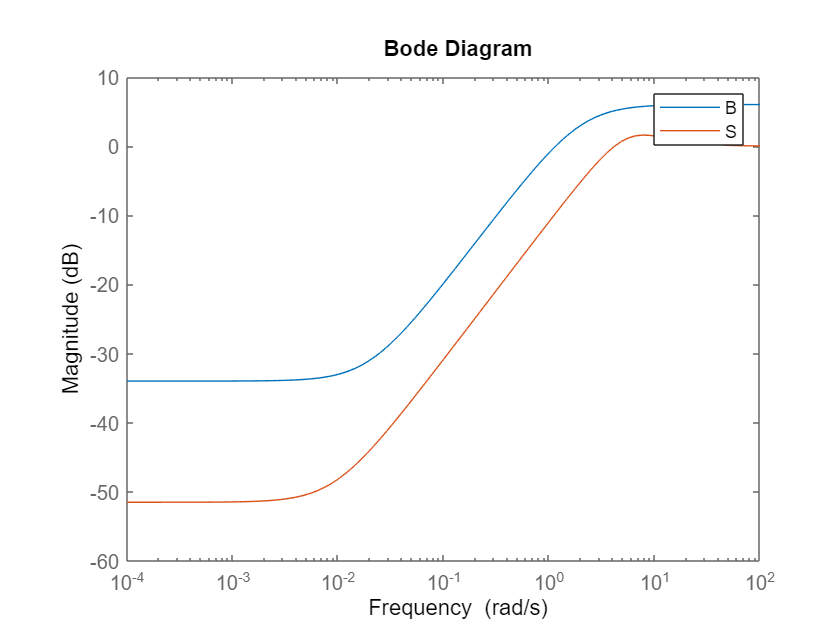

figure()
bodemag(B)
hold on
bodemag(S)
legend()

#### Part c

% m_u = 2150 + 150 * ureal('delta_m',0);
% b_u = b * (1 + 0.2*ureal('delta_b',0));
% c_u = c * (1 + 0.1*ureal('delta_c',0));
% tau_u = ureal('tau_u',0.1, 'Range', [0.05, 0.2]);
% P_u = tf([1], [tau_u 1]) * tf([c_u], [m_u b_u]);
% Ploting Relative Uncertainties
w = logspace(-2,4,500);
P_mag = bode(P,w);
figure
hold on
for i = 1:20
    % using braket indexing bc otherwise I get cell errors... cells are
    % wonderful
%     P_hat{i} = usample(P_u);

    % Just realized we were not supposed to use ureal... so:
    % --------------
    m_u{i} = 2150 + 150*(2*rand()-1);
    b_u{i} = b * (1 + 0.2*(2*rand()-1));
    c_u{i} = c * (1 + 0.1*(2*rand()-1));
    tau_u{i} = 0.05 + 0.15*rand();    
    P_hat{i} = tf([1], [tau_u{i} 1]) * tf([c_u{i}], [m_u{i} b_u{i}]);
    % -------------------------------

    [P_hat_mag{i}, ~, ~] = bode(P_hat{i},w);
    R{i} = reshape(abs(P_hat_mag{i} - P_mag)./ abs(P_mag),[],1);
    plot(w,R{i})
end
% set(gca, 'YScale', 'log')
set(gca, 'XScale', 'log')


Arbritrarily selected values to make it fit... W(s) could probbably be derived as well based on the extremes of the uncertainty (by that I mean it is a simple caluculation with only 5 variables with defined ranges)

a1 = 1.25;
a2 = 0.5;
a3 = 2;
W_u = tf([a1 a2], [1 a3])

W_u =
 
  1.25 s + 0.5
  ------------
     s + 2
 
Continuous-time transfer function.



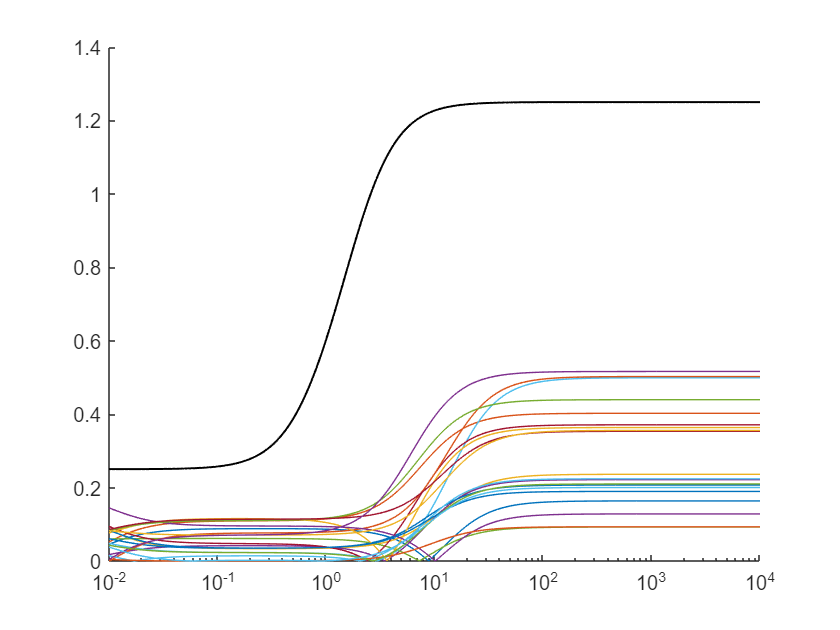

[W_u_mag, ~, ~] = bode(W_u,w);
plot(w,reshape(W_u_mag,[],1),'k',LineWidth=1)

## Part d

for i = 1:20
    P_cls_stable(i) = isstable(1 + C * P_hat{i});
end
P_cls_stable

P_cls_stable = 1×20 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


According to the simplistic test of stability for each of the sampled systems, the answer is clearly yes.

A better method of confirming this would be to actully prove it for the entire region, which I may or may not make time for...

## Part e

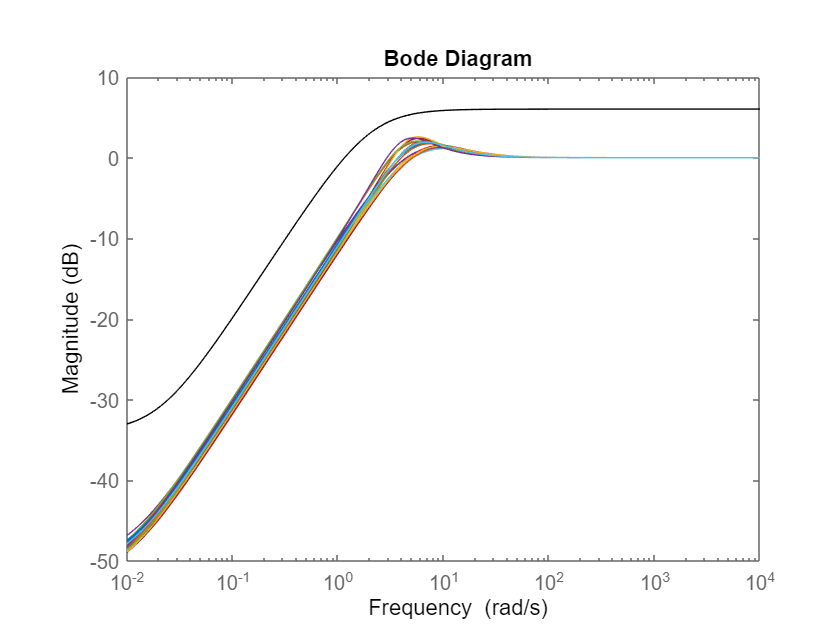

figure
hold on
for i = 1:20
    S_hat{i} = (1) / (1 + C*P_hat{i});
    bodemag(S_hat{i},w)
end
bodemag(B,w, 'k')

Acording to bode diagram, the controller does meet performance specifications.